## PROJETO BALANÇA

Primeiro se adquire os dados experimentais da medida da deformação sofrida pela força peso na mola como também os dados dos pesos que foram submetidos as molas.

### Leitura dos Dados

os dados da tabela vão ser lidos através de uma tabela com extensão .xlsx

clear;clc;
dados = xlsread("balanca.xlsx");
vetorDeformacao = dados(:,1);
vetorMassa = dados(:,2);

### Criação da Estrutura de Dados

mola = struct('Deformacao',vetorDeformacao,'Massa',vetorMassa);

### Cálculo do coeficiente de elasticidade

### 
$$K=\frac{\mathrm{mg}}{\Delta x}$$


Considerando a gravidade da terra: $g_{\mathrm{terra}} =9\ldotp 8\frac{m}{\mathrm{s²}}$

Considerando os dados adquiridos será feito uma comparação e uma média para saber o valor da constante ($K$)

gravidade = 9.8;
vetorK = [];
somaK = 0;
nDados = length(mola.Massa);
for cont = 1:nDados
    vetorK(cont) = (mola.Massa(cont)*gravidade)/mola.Deformacao(cont);
    somaK = somaK + vetorK(cont);
end
K = somaK/length(vetorK)

K = 19.3302

### Lei de Hooke

Pela lei de Hooke se tem o conhecimento que a força elástica que é uma força regenerativa gerada pela mola, tem-se a seguinte fórmula:

### 
$$F_{\mathrm{elástica}} =-K\cdot \Delta X$$


Para cada deformação será plotado a força elástica adquirida. 

**OBS.:**Como o sinal negativo é para indicar sentido da força, não será considerado.

fElastica = mola.Deformacao.*K;

### Plotagem do Gráfico

primeiro, verificou-se o gráfico da deformação em relação a força elástica.

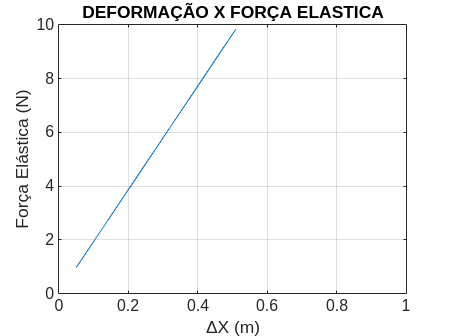

plot(mola.Deformacao,fElastica)
xlabel('ΔX (m)')
ylabel('Força Elástica (N)')
title('DEFORMAÇÃO X FORÇA ELASTICA')
xlim([0 1])
ylim([0 10])
grid on

depois se seguiu verificando em relaçao a massa.

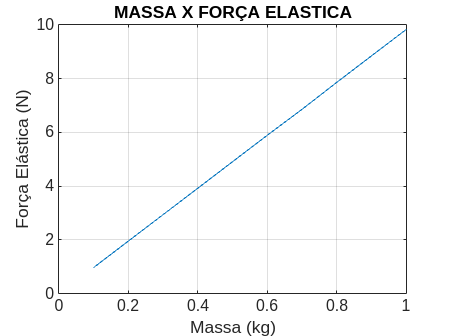

plot(mola.Massa,fElastica)
xlabel('Massa (kg)')
ylabel('Força Elástica (N)')
title('MASSA X FORÇA ELASTICA')
grid on